**1. **An Earth-orbiting satellite is in a 375-km parking orbit. The mission orbit is a 1225- km orbit in the same plane. For each of the orbit transfers below, the initial ∆v puts the satellite on a transfer orbit or trajectory at perigee. The second ∆v transfers the satellite from the transfer orbit to the mission orbit. For each of the orbit transfers, determine the transfer orbit (or trajectory) semimajor axis and eccentricity, and the individual and total ∆v’s. Your answers should be in km and km/s.

- Time of flight is 49 minutes.

- Time of flight is 11 minutes. 

- Time of flight is 7 minutes.

- Time of flight is 5 minutes. 

**Recommendations:** Calculate the time of flight for Hohmann and parabolic transfers, so that you can determine for each given time of flight whether the trajectory is elliptical, parabolic, or hyperbolic. Check your answers using the “easy” time-of-flight calculations as in Homework 4. 

% Constants
mu = 3.986e5; % Gravitational parameter for Earth [km^3/s^2]
R_Earth = 6378; % Radius of Earth [km]

% Orbit radii (include Earth's radius in the calculation)
r_1 = 375 + R_Earth; % Radius of the parking orbit  [km]
r_2 = 1225 + R_Earth; % Radius of the mission orbit [km]

% Velocities in initial and final orbits
v_1 = sqrt(mu / r_1); % velocity in the parking orbit
v_2 = sqrt(mu / r_2); % velocity in the mission orbit

[dv_1_h, dv_2_h, dv_t_h, T_Hohmann] = hohmann_transfer(r_1, r_2, mu);
T_Hohmann_min = T_Hohmann/60;

% Given parameters for a parabolic orbit
r_p = r_1;    % Periapsis distance
p = 2 * r_p; % Semi-latus rectum for a parabolic orbit

v_init = sqrt(mu * (2 / r_1));
v_final = sqrt(mu * (2 / r_2));
dv_1 = abs(v_init - v_1); % first burn (at periapsis)
dv_2 = abs(v_2 - v_final); % second burn (at apoapsis)
dv_t_par = dv_1 + dv_2;

nu_2 = acos((p - r_2) / r_2);

% Calculate the time of flight for a parabolic trajectory
D = sqrt(p)*tan(nu_2/2);
T_par = 1/(2*sqrt(mu))*(p*D + D^3/3);

% Convert time to minutes and display the result
T_par_min = T_par / 60;

v_init = sqrt(mu * (2 / r_1));
v_final = sqrt(mu * (2 / r_2));
dv_1 = abs(v_init - v_1); % first burn (at periapsis)
dv_2 = abs(v_2 - v_final); % second burn (at apoapsis)
dv_t = dv_1 + dv_2;

% Display results
fprintf('Hohmann TOF (minutes): %.2f\n', T_Hohmann_min);

Hohmann TOF (minutes): 50.44


fprintf('Hohmann dv (km/s): %.2f\n', dv_t_h);

Hohmann dv (km/s): 0.44


fprintf('Parabolic TOF (minutes): %.2f\n', T_par_min);

Parabolic TOF (minutes): 7.66


fprintf('Parabolic dv (km/s): %.2f\n', dv_t_par);

Parabolic dv (km/s): 6.18



% Eccentricity vector
e_vec = [0.0592:0.000001:0.99999, 1:0.0000001:3];
a_vec = r_p ./ (1 - e_vec);
[dv_1, dv_2, dv_t, dt, orbit_type] = calc_orb_man(r_1, r_2, e_vec, mu);

% Convert dt to minutes
dt_min = dt / 60;

% Define time of flight targets
tof_targets = [49; 11; 7; 5]; % minutes
tol = 0.001; % Tolerance for finding the time of flight

% Initialize results storage
results = struct('tof', [], 'a', [], 'e', [], 'dv_1', [], 'dv_2', [], 'dv_t', []);

% Loop through each target ToF
for i = 1:length(tof_targets)
    % Find indices where the time of flight is close to the target
    indices = find(abs(dt_min - tof_targets(i)) < tol);

    if ~isempty(indices)
        % Store results for each found ToF
        for j = 1:length(indices)
            index = indices(j);
            results(i).tof = dt_min(index);
            results(i).a = r_1 / (1 - e_vec(index));
            results(i).e = e_vec(index);
            results(i).dv_1 = dv_t(index);
            results(i).dv_2 = dv_t(index);
            results(i).dv_t = dv_t(index);
        end
    end
end

figure;
plot(dv_t, dt_min, 'b-'); % Original plot of Delta-v vs. TOF

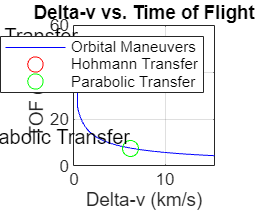

hold on;

% Plot Hohmann transfer point
plot(dv_1_h + dv_2_h, T_Hohmann_min, 'ro', 'MarkerSize', 8); % Hohmann transfer point
text(dv_1_h + dv_2_h, T_Hohmann_min, ' Hohmann Transfer', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');

% Plot parabolic transfer point
plot(dv_t_par, T_par_min, 'go', 'MarkerSize', 8); % Parabolic transfer point
text(dv_t_par, T_par_min, ' Parabolic Transfer', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');

xlabel('Delta-v (km/s)');
ylabel('TOF (min)');
grid on;
axis square;
title('Delta-v vs. Time of Flight');
legend('Orbital Maneuvers', 'Hohmann Transfer', 'Parabolic Transfer');
hold off;

**2/3. **Following the examples in the “Pop Quizzes” for the f and g method for elliptical orbits, devise and solve a problem of the form: 

An Earth-orbiting satellite has the following position and velocity vectors at t0:

your equations for r and v go here What are the position and velocity vectors xxx minutes later? Use the f and g method with ∆E. Check your answers.

clear
clc

mu = 398600;
r_1_vec = [-3601.4; 3601.4; 5093.1];
r_2_vec = [-6180.8; 1172.7; 5199.7];
tof = 12 * 60;

root_solver = 'linear';
orbit = 'short';

[v_1_vec, v_2_vec, p_vec] = lambert_solver(root_solver, r_1_vec, r_2_vec, tof, mu, orbit);

[r_2_vec, v_2_vec] = orbit_prop_fg(r_1_vec, v_1_vec, tof, mu);
